clearvars;
load("BackupData.mat")

%Creates tables to display the results
%The table is done this way to allow for
%quicker table modifications.
disp('Triangle Arm / Model 1 Table');

Triangle Arm / Model 1 Table


disp(Show1);

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable    Max_Disp_mm    Max_Stress_MPa    Factor_of_Safety    Thrust_to_Weight_Ratio    Total_Cost_Vol_USD    Total_Cost_mass_USD
    _______________________________    ______________    ______________    __________    ___________    ______________    ________________    ______________________    __________________    ___________________

    "Carbon Fiber Composite (CFRP)"       0.042778          0.82889          "Yes"         0.88702          24.564             24.426                   2                       2.8875                13.65      
    "Aluminum Alloy"         


disp('|');disp('|');disp('|'); %For spacing in the program

|
|
|


disp('Circle Arm / Model 2 Table');

Circle Arm / Model 2 Table


disp(Show2);

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable    Max_Disp_mm    Max_Stress_MPa    Factor_of_Safety    Thrust_to_Weight_Ratio    Total_Cost_Vol_USD    Total_Cost_mass_USD
    _______________________________    ______________    ______________    __________    ___________    ______________    ________________    ______________________    __________________    ___________________

    "Carbon Fiber Composite (CFRP)"       0.024813          0.90075          "Yes"         0.21511          15.817             37.934                   2                       2.4322               4.3238      
    "Aluminum Alloy"         


disp('|');disp('|');disp('|'); %For spacing in the program

|
|
|


disp('Beam Arm / Model 3 Table');

Beam Arm / Model 3 Table


disp(Show3);

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable    Max_Disp_mm    Max_Stress_MPa    Factor_of_Safety    Thrust_to_Weight_Ratio    Total_Cost_Vol_USD    Total_Cost_mass_USD
    _______________________________    ______________    ______________    __________    ___________    ______________    ________________    ______________________    __________________    ___________________

    "Carbon Fiber Composite (CFRP)"       0.026745          0.89302          "Yes"         0.97521          56.122             10.691                   2                       2.592                4.608       
    "Aluminum Alloy"         


disp('|');disp('|');disp('|'); %For spacing in the program

|
|
|


disp('Lattice Arm / Model 4 Table');

Lattice Arm / Model 4 Table


disp(Show4);

               Material                Mass_of_Arm_kg    Max_Payload_kg    Acceptable    Max_Disp_mm    Max_Stress_MPa    Factor_of_Safety    Thrust_to_Weight_Ratio    Total_Cost_Vol_USD    Total_Cost_mass_USD
    _______________________________    ______________    ______________    __________    ___________    ______________    ________________    ______________________    __________________    ___________________

    "Carbon Fiber Composite (CFRP)"       0.091297          0.63481          "Yes"        0.057522          7.8082             76.842                   2                      14.855                26.409      
    "Aluminum Alloy"         


%Max_Displacement = max(Result.Displacement.Magnitude)
%Max_Stress = max(Result.VonMisesStress)
%FoS = materials(1).yieldStrength_Pa/Max_Stress

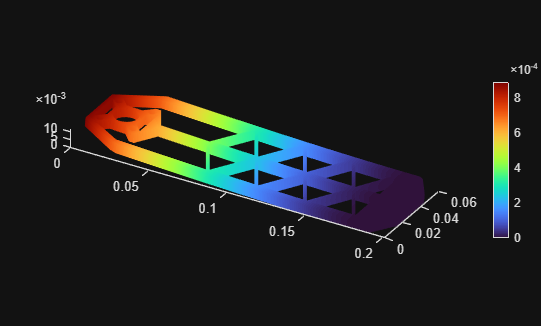

% Data to visualize
meshData = Model_1_result_Al_Alloy.Mesh;
nodalData = Model_1_result_Al_Alloy.Displacement.Magnitude;
deformationData = Model_1_result_Al_Alloy.Displacement;

% Create PDE result visualization
resultViz2 = pdeviz(meshData,abs(real(nodalData)), ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",6.7386, ...
    "ColorLimits",[0 0.0008904]);


% Clear temporary variables
clearvars meshData nodalData deformationData